%% formation through rigidity theory

clear 
close all


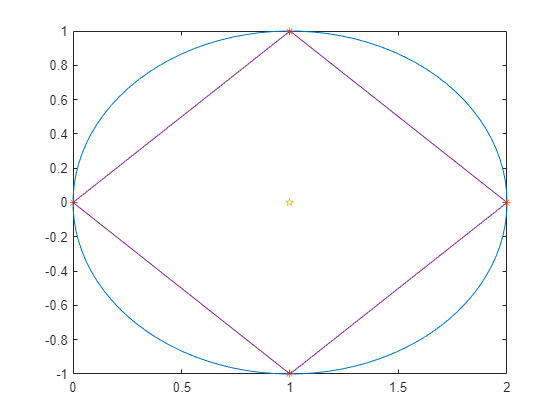

% initialize UGV struct
ugv.xw = 1;  ugv.yw = 0; ugv.hw = 0;    % robot position and orientation wrt world frame


n=4;             % number of vertex of the regular polygon formation (for now, set it to 4)
r=1;             % ray of the circumscribed circle 
x = ugv.xw;      % coordinate for the centre of the formation
y = ugv.yw;

vertix_x = [];   % initialization of x coords of desired formation
vertix_y = [];   % initialization of y coords of desired formation

for i = 0:n
       vertix_x(end+1) = x + r * cos(2 * pi * i / n);    % evaluation of x vertices
       vertix_y(end+1) = y + r * sin(2 * pi * i / n);    % evaluation of y vertices
end

% plotting the formation used as input to the problem 
ray = r;
xc = x;
yc = y;

theta = linspace(0,2*pi);
x = ray*cos(theta) + xc;
y = ray*sin(theta) + yc;

convex_hull_desired= [vertix_x(1), vertix_y(1); vertix_x(2), vertix_y(2); vertix_x(3), vertix_y(3); vertix_x(4), vertix_y(4)];
[k,av] = convhull(convex_hull_desired);

plot(x,y)
hold on
plot(convex_hull_desired(:,1),convex_hull_desired(:,2),'*')
hold on
plot(ugv.xw, ugv.yw, 'p')
plot(convex_hull_desired(k,1),convex_hull_desired(k,2))

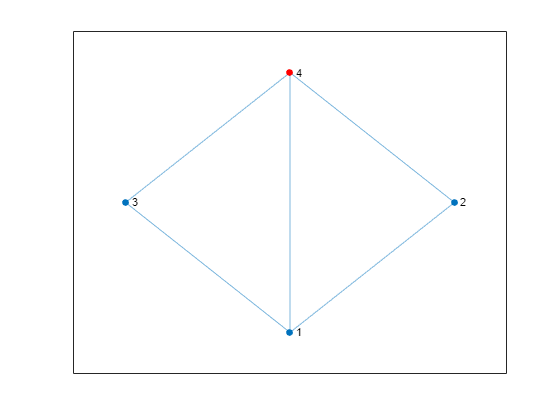

% initialize AUV struct - line formation
auv.id = [ 1  2  3  4 ].';      % auv id 
auv.xw = [2 -0.8 1.6 -2 ].';    % coords in world frame
auv.yw = [-1 -1 1.5 -3.5 ].';
auv.hw = [ 0  0  0  0 ].';      % heading angle in world frame

auv.n  = n;                     % number of auvs

%% building the graph topography: the important property that the graph must
% show is that it must be a minimally infinitesimally rigid graph (checking the rigidity matrix rank)
% The main idea behind this two property is that a variation of the
% configuration of the formation always lead to translation or scaling
% transformation. These factors depends on how the distance measurements
% are setted between the UAVs.

% initilize the nodes; the adjacency matrix is 
% A = adjacency matrix
close all
A = [[0 1 1 1];[1 0 0 1];[1 0 0 1];[1 1 1 0]];
G = graph(A);
h = plot(G);
layout(h,'subspace')
highlight(h, 4,'NodeColor','r')                     % node 4 could be our possible leader

% now, we want to define the edge distance function:
%           |            .              |
%           |            .              |
% f(p) = 1/2|   || p(vi) - p(vj)||^2    |
%           |            .              |
%           |            .              |
% The main idea behind this is that we want to describe our formation only
% through relative distances between UAVs and not through the absolute
% coordinates taken by the vertices of our geometric pattern formation.
% rewriting the current position of drone in a more synthetic way:

p1x = auv.xw(1);
p1y = auv.yw(1);

p2x = auv.xw(2);
p2y = auv.yw(2);

p3x = auv.xw(3);
p3y = auv.yw(3);

p4x = auv.xw(4);
p4y = auv.yw(4);



f_d = [(1/2)*(p1x-p2x)^2+(p1y-p2y)^2;   % dist 12
       (1/2)*(p1x-p3x)^2+(p1y-p3y)^2;   % dist 13
       (1/2)*(p1x-p4x)^2+(p1y-p4y)^2;   % dist 14
       (1/2)*(p2x-p4x)^2+(p2y-p4y)^2;   % dist 24
       (1/2)*(p3x-p4x)^2+(p3y-p4y)^2;]; % dist 34
% the Rigidity matrix correspond to the derivative of the edge distance
% function. If we consider a variation on the configuration of the
% formation, the rigidity matrix correspond to the coefficient in which the
% change of configuration affect the geometric pattern:

% f(p + delta_p) = f(p) + R(p)delta_p
% if the rigidity matrix R(p) has 2|v|-3 rank and 2|v|-3 = |e|, than the
% type of modification of the geometric pattern can only deal with
% translation or scaling transformation

% definition of rigidity matrix (by hand):

R_d = [p1x-p2x,p1y-p2y,p1x-p2x,p1y-p2y,0,0,0,0;
       p1x-p3x,p1y-p3y,0,0,p1x-p3x,p1y-p3y,0,0;
       p1x-p4x,p1y-p4y,0,0,0,0,p1x-p4x,p1y-p4y;
       0,0,p2x-p4x,p2y-p4y,0,0,p2x-p4x,p2y-p4y;
       0,0,0,0,p3x-p4x,p3y-p4y,p3x-p4x,p3y-p4y];

desired_rank = 2*auv.n-3;

r = rank(R_d);% the matrix must have rank 2|v| - 3 = |e|, namely an minimally infinitesimally rigid graph
if r == desired_rank
    disp('R_d is infinitesimally minimally rigid graph; stability ensured with this graph')
end

R_d is infinitesimally minimally rigid graph; stability ensured with this graph


% now, we can exploit this property into the ptential field control of
% graph formation framework. In this, the control law is defined for UAVs
% with dynamics equivalent to an integrator. The stability analysis is
% defined in a non-linear framework: the Lyapunov function used is:

% V_ij(p) = 1/4(||p_i(t) - p_j(t)||^2 - d_ij^2)(p_i(t) - p_j(t))
% where p_i(t) is the actual position, while d_ij is the desired relative
% distances

% desired formation relative distances

d12 = 1;
d13 = 1;
d14 = sqrt((vertix_x(1)-vertix_x(4))^2+(vertix_y(1)-vertix_y(4))^2);
d24 = 1;
d34 = 1;


p0 = [p1x, p1y, p2x, p2y, p3x, p3y, p4x, p4y]; %setting the initial condition
tmax = 2;
tspan = [0 tmax];

[t,p] = ode113(@(t,p) odefunSquare(t,p,d12,d13,d14,d24,d34), tspan, p0);
result = p(end, :);
result_x = [result(1), result(3), result(5), result(7)];
result_y = [result(2), result(4), result(6), result(8)];

data_formation = {'desired dist';'obtained dist'};
P12 = [d12; sqrt((result_x(1)-result_x(2))^2+(result_y(1)-result_y(2))^2)];
P13 = [d13; sqrt((result_x(1)-result_x(3))^2+(result_y(1)-result_y(3))^2)];
P14 = [d14; sqrt((result_x(1)-result_x(4))^2+(result_y(1)-result_y(4))^2)];
P24 = [d24; sqrt((result_x(2)-result_x(4))^2+(result_y(2)-result_y(4))^2)];
P34 = [d34; sqrt((result_x(3)-result_x(4))^2+(result_y(3)-result_y(4))^2)];
X = ['simulation time: ',num2str(tmax)];
disp(X)

simulation time: 2


T = table(data_formation,P12,P13,P14,P24,P34)

T = 2×6 table
     data_formation       P12        P13       P14        P24       P34  
    _________________    ______    _______    ______    _______    ______

    {'desired dist' }         1          1    1.4142          1         1
    {'obtained dist'}    1.0038    0.99366    1.4154    0.97708    1.0178


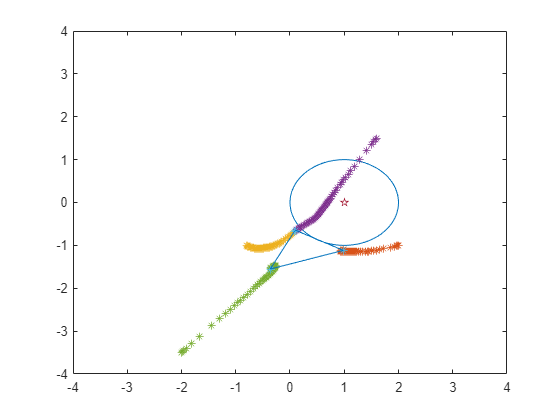

close all 

plot(x,y)
hold on
plot(p(:,1),p(:,2),'*')
hold on 
plot(p(:,3),p(:,4),'*')
hold on 
plot(p(:,5),p(:,6),'*')
hold on 
plot(p(:,7),p(:,8),'*')
hold on 
convex_hull_formation = [result_x(1), result_y(1); result_x(2), result_y(2); result_x(3), result_y(3); result_x(4), result_y(4)];
[k,av] = convhull(convex_hull_formation);

plot(convex_hull_formation(:,1),convex_hull_formation(:,2),'*')
hold on
plot(ugv.xw, ugv.yw, 'p')

plot(convex_hull_formation(k,1),convex_hull_formation(k,2))
axis([-4 4 -4 4])

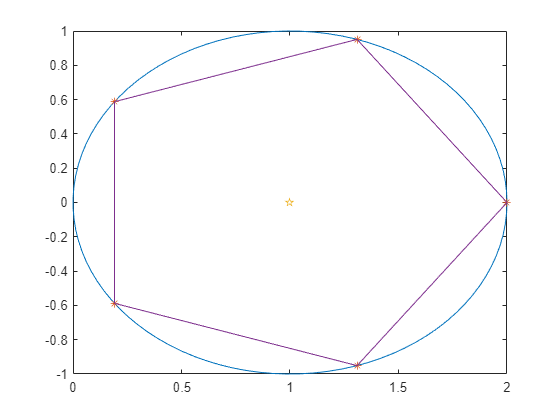

clear 
close all

n=5;             % number of vertex of the regular polygon formation (for now, set it to 4)
r=1;    
ugv.xw = 1;  ugv.yw = 0; ugv.hw = 0;  % ray of the circumscribed circle 
x = ugv.xw;      % coordinate for the centre of the formation
y = ugv.yw;

vertix_x = [];   % initialization of x coords of desired formation
vertix_y = [];   % initialization of y coords of desired formation

for i = 0:n
       vertix_x(end+1) = x + r * cos(2 * pi * i / n);    % evaluation of x vertices
       vertix_y(end+1) = y + r * sin(2 * pi * i / n);    % evaluation of y vertices
end
ray = r;
xc = x;
yc = y;

theta = linspace(0,2*pi);
x = ray*cos(theta) + xc;
y = ray*sin(theta) + yc;


% plotting the formation used as input to the problem 

convex_hull_desired= [vertix_x(1), vertix_y(1); vertix_x(2), vertix_y(2); vertix_x(3), vertix_y(3); vertix_x(4), vertix_y(4);vertix_x(5), vertix_y(5)];
[k,av] = convhull(convex_hull_desired);
plot(x,y)
hold on
plot(convex_hull_desired(:,1),convex_hull_desired(:,2),'*')
hold on
plot(ugv.xw, ugv.yw, 'p')
plot(convex_hull_desired(k,1),convex_hull_desired(k,2))

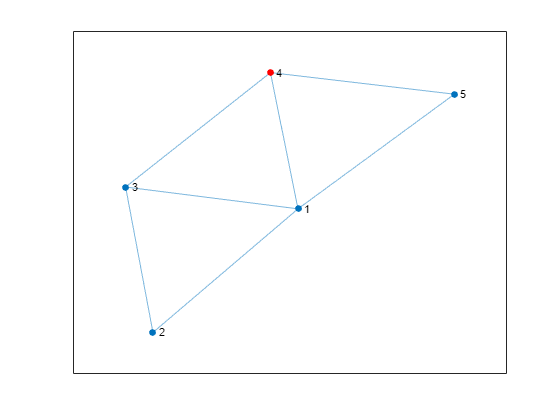

% initialize AUV struct - line formation
auv.id = [ 1  2  3  4  5].';      % auv id 
auv.xw = [-1.5 -2 1.5 1.4 1.5].';    % coords in world frame
auv.yw = [-1.3 -1.5 2 -0.3 -1.8].';
auv.hw = [ 0  0  0  0  0].';      % heading angle in world frame

auv.n  = n;   


% initilize the nodes; the adjacency matrix is 
% A = adjacency matrix
close all
A = [[0 1 1 1 1];[1 0 1 0 0];[1 1 0 1 0];[1 0 1 0 1]; [1 0 0 1 0]];
G = graph(A);
h = plot(G);
highlight(h, 4,'NodeColor','r')  %highlight one as the leader        

% now, we want to define the edge distance function:
%           |            .              |
%           |            .              |
% f(p) = 1/2|   || p(vi) - p(vj)||^2    |
%           |            .              |
%           |            .              |
% The main idea behind this is that we want to describe our formation only
% through relative distances between UAVs and not through the absolute
% coordinates taken by the vertices of our geometric pattern formation.
% rewriting the current position of drone in a more synthetic way:
p1x = auv.xw(1);
p1y = auv.yw(1);

p2x = auv.xw(2);
p2y = auv.yw(2);

p3x = auv.xw(3);
p3y = auv.yw(3);

p4x = auv.xw(4);
p4y = auv.yw(4);

p5x = auv.xw(5);
p5y = auv.yw(5);

f_d = [(1/2)*(p1x-p2x)^2+(p1y-p2y)^2;   % dist 12
       (1/2)*(p1x-p3x)^2+(p1y-p3y)^2;   % dist 13
       (1/2)*(p1x-p4x)^2+(p1y-p4y)^2;   % dist 14
       (1/2)*(p1x-p5x)^2+(p1y-p5y)^2;   % dist 15
       (1/2)*(p2x-p3x)^2+(p2y-p3y)^2;   % dist 23
       (1/2)*(p3x-p4x)^2+(p3y-p4y)^2;   % dist 34
       (1/2)*(p4x-p5x)^2+(p4y-p5y)^2;   % dist 45
       ]; % dist 

% the Rigidity matrix correspond to the derivative of the edge distance
% function. If we consider a variation on the configuration of the
% formation, the rigidity matrix correspond to the coefficient in which the
% change of configuration affect the geometric pattern:

% f(p + delta_p) = f(p) + R(p)delta_p
% if the rigidity matrix R(p) has 2|v|-3 rank and 2|v|-3 = |e|, than the
% type of modification of the geometric pattern can only deal with
% translation or scaling transformation

% definition of rigidity matrix (by hand):

R_d = [p1x-p2x,p1y-p2y,p1x-p2x,p1y-p2y,0,0,0,0,0,0;
       p1x-p3x,p1y-p3y,0,0,p1x-p3x,p1y-p3y,0,0,0,0;
       p1x-p4x,p1y-p4y,0,0,0,0,p1x-p4x,p1y-p4y,0,0;
       p1x-p5x,p1y-p5y,0,0,0,0,0,0,p1x-p5x,p1y-p5y;
       0,0,p2x-p3x,p2y-p3y,p2x-p3x,p2y-p3y,0,0,0,0;
       0,0,0,0,p3x-p4x,p3y-p4y,p3x-p4x,p3y-p4y,0,0;
       0,0,0,0,0,0,p4x-p5x,p4y-p5y,p4x-p5x,p4y-p5y];

desired_rank = 2*auv.n-3;

r = rank(R_d);% the matrix must have rank 2|v| - 3 = |e|, namely an minimally infinitesimally rigid graph
if r == desired_rank
    disp('R_d is infinitesimally minimally rigid graph; stability ensured with this graph')
end

R_d is infinitesimally minimally rigid graph; stability ensured with this graph


d12 = sqrt((vertix_x(1)-vertix_x(2))^2+(vertix_y(1)-vertix_y(2))^2);
d13 = sqrt((vertix_x(1)-vertix_x(3))^2+(vertix_y(1)-vertix_y(3))^2);
d14 = sqrt((vertix_x(1)-vertix_x(4))^2+(vertix_y(1)-vertix_y(4))^2);
d15 = sqrt((vertix_x(1)-vertix_x(5))^2+(vertix_y(1)-vertix_y(5))^2);
d23 = sqrt((vertix_x(2)-vertix_x(3))^2+(vertix_y(2)-vertix_y(3))^2);
d34 = sqrt((vertix_x(3)-vertix_x(4))^2+(vertix_y(3)-vertix_y(4))^2);
d45 = sqrt((vertix_x(4)-vertix_x(5))^2+(vertix_y(4)-vertix_y(5))^2);

p0 = [p1x, p1y, p2x, p2y, p3x, p3y, p4x, p4y, p5x, p5y]; % setting the initial conditions

tmax = 2;
tspan = [0 tmax];

[t,p] = ode113(@(t,p) odefunPentagon(t,p,d12,d13,d14,d15,d23,d34,d45), tspan, p0);
result = p(end, :);
result_x = [result(1), result(3), result(5), result(7), result(9)];
result_y = [result(2), result(4), result(6), result(8), result(10)];

close all

data_formation = {'desired dist';'obtained dist'};
P12 = [d12; sqrt((result_x(1)-result_x(2))^2+(result_y(1)-result_y(2))^2)];
P13 = [d13; sqrt((result_x(1)-result_x(3))^2+(result_y(1)-result_y(3))^2)];
P14 = [d14; sqrt((result_x(1)-result_x(4))^2+(result_y(1)-result_y(4))^2)];
P15 = [d15; sqrt((result_x(1)-result_x(5))^2+(result_y(1)-result_y(5))^2)];
P23 = [d23; sqrt((result_x(2)-result_x(3))^2+(result_y(2)-result_y(3))^2)];
P34 = [d34; sqrt((result_x(3)-result_x(4))^2+(result_y(3)-result_y(4))^2)];
P45 = [d45; sqrt((result_x(4)-result_x(5))^2+(result_y(4)-result_y(5))^2)];
X = ['simulation time: ',num2str(tmax)];
disp(X)

simulation time: 2


T = table(data_formation,P12,P13,P14,P15,P23,P34,P45)

T = 2×8 table
     data_formation       P12       P13       P14       P15       P23       P34       P45  
    _________________    ______    ______    ______    ______    ______    ______    ______

    {'desired dist' }    1.1756    1.9021    1.9021    1.1756    1.1756    1.1756    1.1756
    {'obtained dist'}      1.18    1.9018    1.9019    1.1799    1.1791    1.1786     1.179


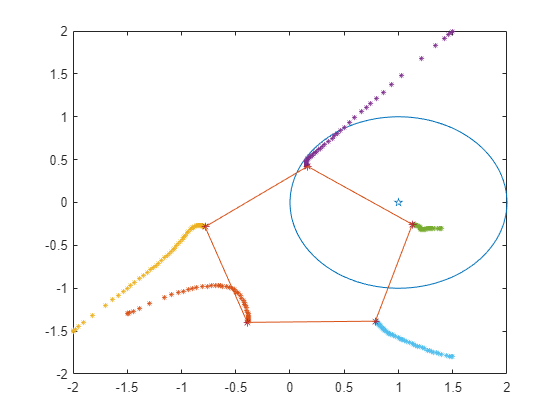


plot(x,y)
hold on
plot(p(:,1),p(:,2),'*','MarkerSize', 4)
hold on 
plot(p(:,3),p(:,4),'*','MarkerSize', 4)
hold on 
plot(p(:,5),p(:,6),'*','MarkerSize', 4)
hold on 
plot(p(:,7),p(:,8),'*','MarkerSize', 4)
hold on 
plot(p(:,9),p(:,10),'*','MarkerSize', 4)
convex_hull_formation = [result_x(1), result_y(1); result_x(2), result_y(2); result_x(3), result_y(3); result_x(4), result_y(4); result_x(5), result_y(5)];
[k,av] = convhull(convex_hull_formation);

plot(convex_hull_formation(:,1),convex_hull_formation(:,2),'*')
hold on
plot(ugv.xw, ugv.yw, 'p')

plot(convex_hull_formation(k,1),convex_hull_formation(k,2))


close all
tmax = 10;
tspan = [0 tmax];

[t,p] = ode113(@(t,p) odefunPentagonMotion(t,p,d12,d13,d14,d15,d23,d34,d45, 1, 0.5*cos(0.3*pi*t)), tspan, p0);
result = p(end, :);
result_x = [result(1), result(3), result(5), result(7), result(9)];
result_y = [result(2), result(4), result(6), result(8), result(10)];
len = length(p);



first_sample = round(len/4);
second_sample = round(len/2);
third_sample = round(len*(3/4));

result_first_sample = p(first_sample, :);

result_x_first_sample = [result_first_sample(1), result_first_sample(3), result_first_sample(5),...
result_first_sample(7), result_first_sample(9)];
result_y_first_sample = [result_first_sample(2), result_first_sample(4), result_first_sample(6),...
    result_first_sample(8), result_first_sample(10)];


result_second_sample = p(second_sample, :);
result_x_second_sample = [result_second_sample(1), result_second_sample(3), result_second_sample(5),...
    result_second_sample(7), result_second_sample(9)];
result_y_second_sample = [result_second_sample(2), result_second_sample(4), result_second_sample(6),...
    result_second_sample(8), result_second_sample(10)];


result_third_sample = p(third_sample, :);
result_x_third_sample = [result_third_sample(1), result_third_sample(3), result_third_sample(5),...
    result_third_sample(7), result_third_sample(9)];
result_y_third_sample = [result_third_sample(2), result_third_sample(4), result_third_sample(6),...
    result_third_sample(8), result_third_sample(10)];

data_formation = {'desired dist';'obtained dist 0.25 sim'; 'obtained dist 0.5 sim'; 'obtained dist 0.75 sim'; 'obtained dist sim complete'};
P12 = [d12;sqrt((result_x_first_sample(1)-result_x_first_sample(2))^2+(result_y_first_sample(1)-result_y_first_sample(2))^2);
    sqrt((result_x_second_sample(1)-result_x_second_sample(2))^2+(result_y_second_sample(1)-result_y_second_sample(2))^2);
    sqrt((result_x_third_sample(1)-result_x_third_sample(2))^2+(result_y_third_sample(1)-result_y_third_sample(2))^2);
    sqrt((result_x(1)-result_x(2))^2+(result_y(1)-result_y(2))^2)];

P13 = [d13; sqrt((result_x_first_sample(1)-result_x_first_sample(3))^2+(result_y_first_sample(1)-result_y_first_sample(3))^2);
    sqrt((result_x_second_sample(1)-result_x_second_sample(3))^2+(result_y_second_sample(1)-result_y_second_sample(3))^2);
    sqrt((result_x_third_sample(1)-result_x_third_sample(3))^2+(result_y_third_sample(1)-result_y_third_sample(3))^2);
    sqrt((result_x(1)-result_x(3))^2+(result_y(1)-result_y(3))^2)];

P14 = [d14; sqrt((result_x_first_sample(1)-result_x_first_sample(4))^2+(result_y_first_sample(1)-result_y_first_sample(4))^2);
    sqrt((result_x_second_sample(1)-result_x_second_sample(4))^2+(result_y_second_sample(1)-result_y_second_sample(4))^2);
    sqrt((result_x_third_sample(1)-result_x_third_sample(4))^2+(result_y_third_sample(1)-result_y_third_sample(4))^2);
    sqrt((result_x(1)-result_x(4))^2+(result_y(1)-result_y(4))^2)];

P15 = [d15; sqrt((result_x_first_sample(1)-result_x_first_sample(5))^2+(result_y_first_sample(1)-result_y_first_sample(5))^2);
    sqrt((result_x_second_sample(1)-result_x_second_sample(5))^2+(result_y_second_sample(1)-result_y_second_sample(5))^2);
    sqrt((result_x_third_sample(1)-result_x_third_sample(5))^2+(result_y_third_sample(1)-result_y_third_sample(5))^2);
    sqrt((result_x(1)-result_x(5))^2+(result_y(1)-result_y(5))^2)];

P23 = [d23; sqrt((result_x_first_sample(2)-result_x_first_sample(3))^2+(result_y_first_sample(2)-result_y_first_sample(3))^2);
    sqrt((result_x_second_sample(2)-result_x_second_sample(3))^2+(result_y_second_sample(2)-result_y_second_sample(3))^2);
    sqrt((result_x_third_sample(2)-result_x_third_sample(3))^2+(result_y_third_sample(2)-result_y_third_sample(3))^2);
    sqrt((result_x(2)-result_x(3))^2+(result_y(2)-result_y(3))^2)];

P34 = [d34; sqrt((result_x_first_sample(3)-result_x_first_sample(4))^2+(result_y_first_sample(3)-result_y_first_sample(4))^2);
    sqrt((result_x_second_sample(3)-result_x_second_sample(4))^2+(result_y_second_sample(3)-result_y_second_sample(4))^2);
    sqrt((result_x_third_sample(3)-result_x_third_sample(4))^2+(result_y_third_sample(3)-result_y_third_sample(4))^2);
    sqrt((result_x(3)-result_x(4))^2+(result_y(3)-result_y(4))^2)];

P45 = [d45; sqrt((result_x_first_sample(4)-result_x_first_sample(5))^2+(result_y_first_sample(4)-result_y_first_sample(5))^2);
    sqrt((result_x_second_sample(4)-result_x_second_sample(5))^2+(result_y_second_sample(4)-result_y_second_sample(5))^2);
    sqrt((result_x_third_sample(4)-result_x_third_sample(5))^2+(result_y_third_sample(4)-result_y_third_sample(5))^2);
    sqrt((result_x(4)-result_x(5))^2+(result_y(4)-result_y(5))^2)];

X = ['simulation time: ',num2str(tmax)];
disp(X)

simulation time: 10



T = table(data_formation,P12,P13,P14,P15,P23,P34,P45)

T = 5×8 table
            data_formation             P12       P13       P14       P15       P23       P34       P45  
    ______________________________    ______    ______    ______    ______    ______    ______    ______

    {'desired dist'              }    1.1756    1.9021    1.9021    1.1756    1.1756    1.1756    1.1756
    {'obtained dist 0.25 sim'    }    1.1932    1.8844    1.8871    1.2222    1.2444    1.2369    1.2228
    {'obtained dist 0.5 sim'     }    1.1761    1.9025    1.9025    1.1761    1.1759    1.1759    1.1759
    {'obtained dist 0.75 sim'    }    1.1758    1.9026    1.9026    1.1758    1.1757    1.1757    1.1757
    {'obtained dist sim complete'}    1.1755     1.902     1.902    1.1755    1.175

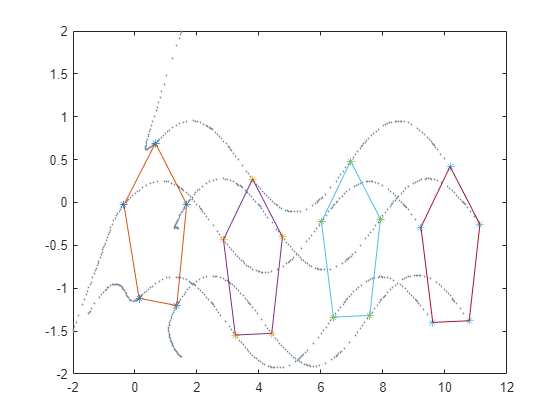


plot(p(:,1),p(:,2),'.', 'MarkerSize', 4, 'Color', '#778899')
hold on 
plot(p(:,3),p(:,4),'.','MarkerSize', 4, 'Color', '#778899')
hold on 
plot(p(:,5),p(:,6),'.','MarkerSize', 4, 'Color', '#778899')
hold on 
plot(p(:,7),p(:,8),'.', 'MarkerSize', 4,'Color', '#778899')
hold on 
plot(p(:,9),p(:,10),'.','MarkerSize', 4, 'Color', '#778899')
hold on

convex_hull_formation = [result_x(1), result_y(1); result_x(2), result_y(2); result_x(3), result_y(3); result_x(4), result_y(4); result_x(5), result_y(5)];
[h,av] = convhull(convex_hull_formation);
plot(convex_hull_formation(:,1),convex_hull_formation(:,2),'*')
hold on
plot(convex_hull_formation(h,1),convex_hull_formation(h,2))
hold on

convex_hull_formation_first_sample = [result_x_first_sample(1), result_y_first_sample(1); result_x_first_sample(2), result_y_first_sample(2);
    result_x_first_sample(3), result_y_first_sample(3); result_x_first_sample(4), result_y_first_sample(4);
    result_x_first_sample(5), result_y_first_sample(5)];
[n,av] = convhull(convex_hull_formation_first_sample);
plot(convex_hull_formation_first_sample(:,1),convex_hull_formation_first_sample(:,2),'*')
hold on
plot(convex_hull_formation_first_sample(n,1),convex_hull_formation_first_sample(n,2))
hold on

convex_hull_formation_second_sample = [result_x_second_sample(1), result_y_second_sample(1); result_x_second_sample(2), result_y_second_sample(2);
    result_x_second_sample(3), result_y_second_sample(3); result_x_second_sample(4), result_y_second_sample(4); 
    result_x_second_sample(5), result_y_second_sample(5)];
[m,av] = convhull(convex_hull_formation_second_sample);
plot(convex_hull_formation_second_sample(:,1),convex_hull_formation_second_sample(:,2),'*')
hold on
plot(convex_hull_formation_second_sample(k,1),convex_hull_formation_second_sample(m,2))
hold on

convex_hull_formation_third_sample = [result_x_third_sample(1), result_y_third_sample(1); result_x_third_sample(2), result_y_third_sample(2);
    result_x_third_sample(3), result_y_third_sample(3); result_x_third_sample(4), result_y_third_sample(4);
    result_x_third_sample(5), result_y_third_sample(5)];
[k,av] = convhull(convex_hull_formation_third_sample);
plot(convex_hull_formation_third_sample(:,1),convex_hull_formation_third_sample(:,2),'*')
hold on
plot(convex_hull_formation_third_sample(k,1),convex_hull_formation_third_sample(k,2))
hold on

% for the resolution of the differential eq.:

% p(1) = p1x; p(2) = p2y; p(3) = p2x; p(4) = p2y; p(5) = p3x; p(6) = p3y; p(7) = p4x; p(8) = p4y; p(9) = p5x; p(10) = p5y;

function dpdt = odefunSquare(t,p,d12,d13,d14,d24,d34)
dpdt = zeros(8,1);
dpdt(1) = -((((p(1)-p(3))^2+(p(2)-p(4))^2)-(d12^2))*(p(1)-p(3)) + (((p(1)-p(5))^2+(p(2)-p(6))^2)-(d13^2))*(p(1)-p(5)) + (((p(1)-p(7))^2+(p(2)-p(8))^2)-(d14^2))*(p(1)-p(7)));
dpdt(2) = -((((p(1)-p(3))^2+(p(2)-p(4))^2)-(d12^2))*(p(2)-p(4)) + (((p(1)-p(5))^2+(p(2)-p(6))^2)-(d13^2))*(p(2)-p(6)) + (((p(1)-p(7))^2+(p(2)-p(8))^2)-(d14^2))*(p(2)-p(8)));

dpdt(3) = -((((p(3)-p(1))^2+(p(4)-p(2))^2)-(d12^2))*(p(3)-p(1)) + (((p(3)-p(7))^2+(p(4)-p(8))^2)-(d24^2))*(p(3)-p(7))); 
dpdt(4) = -((((p(3)-p(1))^2+(p(4)-p(2))^2)-(d12^2))*(p(4)-p(2)) + (((p(3)-p(7))^2+(p(4)-p(8))^2)-(d24^2))*(p(4)-p(8)));

dpdt(5) = -((((p(5)-p(1))^2+(p(6)-p(2))^2)-(d13^2))*(p(5)-p(1)) + (((p(5)-p(7))^2+(p(6)-p(8))^2)-(d34^2))*(p(5)-p(7)));
dpdt(6) = -((((p(5)-p(1))^2+(p(6)-p(2))^2)-(d13^2))*(p(6)-p(2)) + (((p(5)-p(7))^2+(p(6)-p(8))^2)-(d34^2))*(p(6)-p(8)));

dpdt(7) = -((((p(7)-p(1))^2+(p(8)-p(2))^2)-(d14^2))*(p(7)-p(1)) + (((p(7)-p(3))^2+(p(8)-p(4))^2)-(d24^2))*(p(7)-p(3)) + (((p(7)-p(5))^2+(p(8)-p(6))^2)-(d34^2))*(p(7)-p(5)));
dpdt(8) = -((((p(7)-p(1))^2+(p(8)-p(2))^2)-(d14^2))*(p(8)-p(2)) + (((p(7)-p(3))^2+(p(8)-p(4))^2)-(d24^2))*(p(8)-p(4)) + (((p(7)-p(5))^2+(p(8)-p(6))^2)-(d34^2))*(p(8)-p(6)));

end


function dpdt = odefunPentagon(t,p,d12,d13,d14,d15,d23,d34,d45)
dpdt = zeros(10,1);
dpdt(1) = -((((p(1)-p(3))^2+(p(2)-p(4))^2)-(d12^2))*(p(1)-p(3)) + (((p(1)-p(5))^2+(p(2)-p(6))^2)-(d13^2))*(p(1)-p(5)) ...
        + (((p(1)-p(7))^2+(p(2)-p(8))^2)-(d14^2))*(p(1)-p(7)) + (((p(1)-p(9))^2+(p(2)-p(10))^2)-(d15^2))*(p(1)-p(9)));
dpdt(2) = -((((p(1)-p(3))^2+(p(2)-p(4))^2)-(d12^2))*(p(2)-p(4)) + (((p(1)-p(5))^2+(p(2)-p(6))^2)-(d13^2))*(p(2)-p(6)) ...
        + (((p(1)-p(7))^2+(p(2)-p(8))^2)-(d14^2))*(p(2)-p(8))+ (((p(1)-p(9))^2+(p(2)-p(10))^2)-(d15^2))*(p(2)-p(10)));

dpdt(3) = -((((p(3)-p(1))^2+(p(4)-p(2))^2)-(d12^2))*(p(3)-p(1)) + (((p(3)-p(5))^2+(p(4)-p(6))^2)-(d23^2))*(p(3)-p(5))); 
dpdt(4) = -((((p(3)-p(1))^2+(p(4)-p(2))^2)-(d12^2))*(p(4)-p(2)) + (((p(3)-p(5))^2+(p(4)-p(6))^2)-(d23^2))*(p(4)-p(6)));

dpdt(5) = -((((p(5)-p(1))^2+(p(6)-p(2))^2)-(d13^2))*(p(5)-p(1)) + (((p(5)-p(7))^2+(p(6)-p(8))^2)-(d34^2))*(p(5)-p(7)) ...
        + (((p(5)-p(3))^2+(p(6)-p(4))^2)-(d23^2))*(p(5)-p(3)));
dpdt(6) = -((((p(5)-p(1))^2+(p(6)-p(2))^2)-(d13^2))*(p(6)-p(2)) + (((p(5)-p(7))^2+(p(6)-p(8))^2)-(d34^2))*(p(6)-p(8)) ...
        + (((p(5)-p(3))^2+(p(6)-p(4))^2)-(d23^2))*(p(6)-p(4)));

dpdt(7) = -((((p(7)-p(1))^2+(p(8)-p(2))^2)-(d14^2))*(p(7)-p(1)) + (((p(7)-p(9))^2+(p(8)-p(10))^2)-(d45^2))*(p(7)-p(9)) ...
        + (((p(7)-p(5))^2+(p(8)-p(6))^2)-(d34^2))*(p(7)-p(5)));
dpdt(8) = -((((p(7)-p(1))^2+(p(8)-p(2))^2)-(d14^2))*(p(8)-p(2)) + (((p(7)-p(9))^2+(p(8)-p(10))^2)-(d45^2))*(p(8)-p(10)) ...
        + (((p(7)-p(5))^2+(p(8)-p(6))^2)-(d34^2))*(p(8)-p(6)));

dpdt(9) = -((((p(9)-p(1))^2+(p(10)-p(2))^2)-(d15^2))*(p(9)-p(1)) + (((p(9)-p(7))^2+(p(10)-p(8))^2)-(d45^2))*(p(9)-p(7))); 
dpdt(10) = -((((p(9)-p(1))^2+(p(10)-p(2))^2)-(d15^2))*(p(10)-p(2)) + (((p(9)-p(7))^2+(p(10)-p(8))^2)-(d45^2))*(p(10)-p(8)));

end


function dpdt = odefunPentagonMotion(t,p,d12,d13,d14,d15,d23,d34,d45,vx,vy)
dpdt = zeros(10,1);
dpdt(1) = -((((p(1)-p(3))^2+(p(2)-p(4))^2)-(d12^2))*(p(1)-p(3)) + (((p(1)-p(5))^2+(p(2)-p(6))^2)-(d13^2))*(p(1)-p(5)) ...
        + (((p(1)-p(7))^2+(p(2)-p(8))^2)-(d14^2))*(p(1)-p(7)) + (((p(1)-p(9))^2+(p(2)-p(10))^2)-(d15^2))*(p(1)-p(9))) + vx;
dpdt(2) = -((((p(1)-p(3))^2+(p(2)-p(4))^2)-(d12^2))*(p(2)-p(4)) + (((p(1)-p(5))^2+(p(2)-p(6))^2)-(d13^2))*(p(2)-p(6)) ...
        + (((p(1)-p(7))^2+(p(2)-p(8))^2)-(d14^2))*(p(2)-p(8))+ (((p(1)-p(9))^2+(p(2)-p(10))^2)-(d15^2))*(p(2)-p(10)))+ vy;

dpdt(3) = -((((p(3)-p(1))^2+(p(4)-p(2))^2)-(d12^2))*(p(3)-p(1)) + (((p(3)-p(5))^2+(p(4)-p(6))^2)-(d23^2))*(p(3)-p(5))) + vx; 
dpdt(4) = -((((p(3)-p(1))^2+(p(4)-p(2))^2)-(d12^2))*(p(4)-p(2)) + (((p(3)-p(5))^2+(p(4)-p(6))^2)-(d23^2))*(p(4)-p(6)))+ vy;

dpdt(5) = -((((p(5)-p(1))^2+(p(6)-p(2))^2)-(d13^2))*(p(5)-p(1)) + (((p(5)-p(7))^2+(p(6)-p(8))^2)-(d34^2))*(p(5)-p(7)) ...
        + (((p(5)-p(3))^2+(p(6)-p(4))^2)-(d23^2))*(p(5)-p(3)))+ vx;
dpdt(6) = -((((p(5)-p(1))^2+(p(6)-p(2))^2)-(d13^2))*(p(6)-p(2)) + (((p(5)-p(7))^2+(p(6)-p(8))^2)-(d34^2))*(p(6)-p(8)) ...
        + (((p(5)-p(3))^2+(p(6)-p(4))^2)-(d23^2))*(p(6)-p(4)))+ vy;

dpdt(7) = -((((p(7)-p(1))^2+(p(8)-p(2))^2)-(d14^2))*(p(7)-p(1)) + (((p(7)-p(9))^2+(p(8)-p(10))^2)-(d45^2))*(p(7)-p(9)) ...
        + (((p(7)-p(5))^2+(p(8)-p(6))^2)-(d34^2))*(p(7)-p(5))) + vx;
dpdt(8) = -((((p(7)-p(1))^2+(p(8)-p(2))^2)-(d14^2))*(p(8)-p(2)) + (((p(7)-p(9))^2+(p(8)-p(10))^2)-(d45^2))*(p(8)-p(10)) ...
        + (((p(7)-p(5))^2+(p(8)-p(6))^2)-(d34^2))*(p(8)-p(6)))+ vy;

dpdt(9) = -((((p(9)-p(1))^2+(p(10)-p(2))^2)-(d15^2))*(p(9)-p(1)) + (((p(9)-p(7))^2+(p(10)-p(8))^2)-(d45^2))*(p(9)-p(7))) + vx; 
dpdt(10) = -((((p(9)-p(1))^2+(p(10)-p(2))^2)-(d15^2))*(p(10)-p(2)) + (((p(9)-p(7))^2+(p(10)-p(8))^2)-(d45^2))*(p(10)-p(8)))+ vy;

end




